# **NAME        :** R AKHILANDESHWARI

# **REG NO     : **2048046

# **LAB             : **7

## Extract the frame from video

%Extracting the frames from the Video
clf;
vid=VideoReader('AKKI.mp4');
numFrames=vid.NumFrames;
n=numFrames;
for i=1:1:n
    frames=read(vid,i);
    imwrite(frames,['/MATLAB Drive/V2F/',int2str(i),'.jpg']);
end

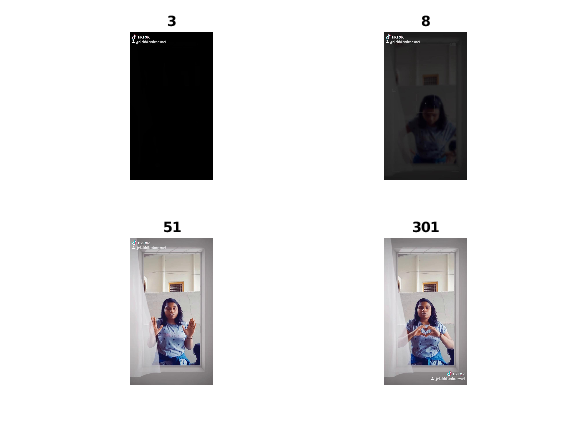

clf;
subplot(221);imshow('/MATLAB Drive/V2F/3.jpg');title('3');
subplot(222);imshow('/MATLAB Drive/V2F/8.jpg');title('8');
subplot(223);imshow('/MATLAB Drive/V2F/51.jpg');title('51');
subplot(224);imshow('/MATLAB Drive/V2F/301.jpg');title('301');

## Applying enhancement methods

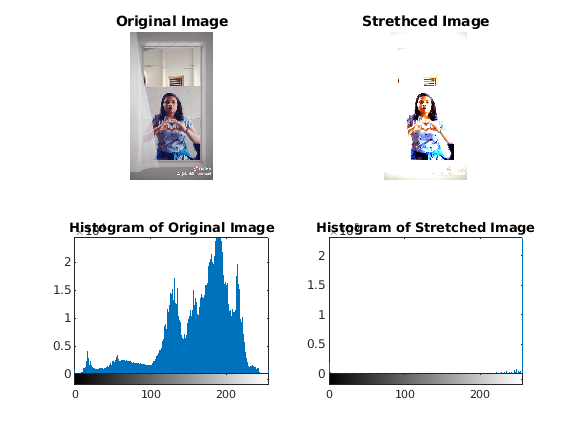

%Contrast stretching the image
clf;
image = imread('/MATLAB Drive/V2F/301.jpg');
stretched_Image = imadjust(image, stretchlim(image, [0.01, 0.17]),[]);
 
subplot(2,2,1), imshow(image), title('Original Image');
subplot(2,2,2), imshow(stretched_Image), title('Strethced Image');
subplot(2,2,3), imhist(image), title('Histogram of Original Image');
subplot(2,2,4), imhist(stretched_Image), title('Histogram of Stretched Image');

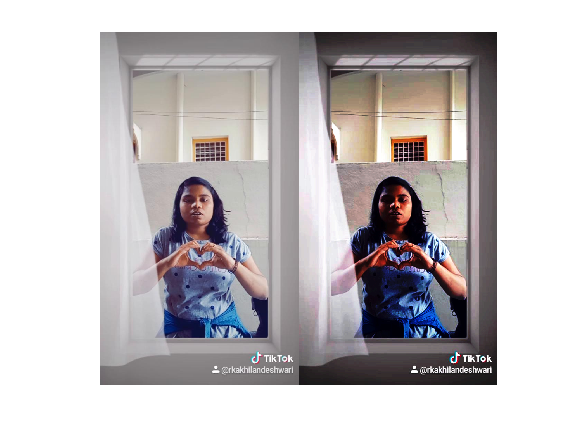

%Auto stretching
clf;
I = imread('/MATLAB Drive/V2F/301.jpg');
J = histeq(I);
imshowpair(I,J,'montage');
axis off;

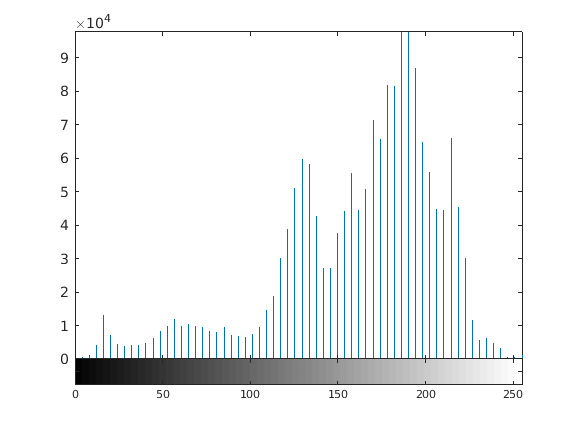

figure
imhist(I,64);

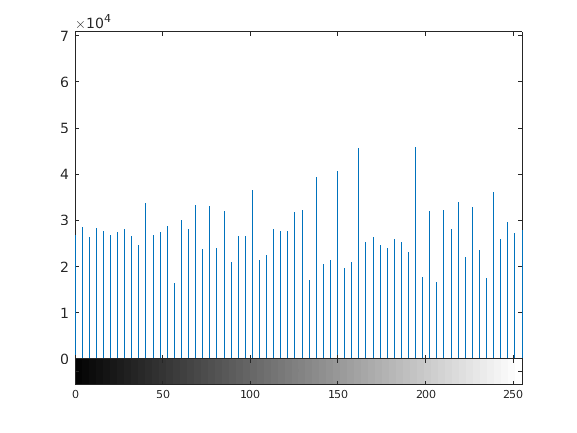

figure
imhist(J,64);

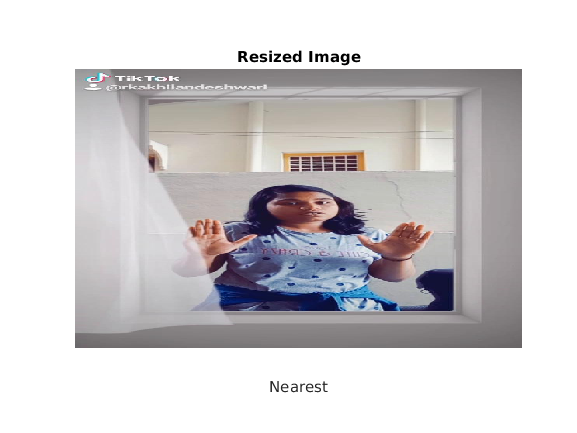

%Resizing the image
I=imread('/MATLAB Drive/V2F/62.jpg');
i=imresize(I,[500,800],'nearest');
imshow(i);title("Resized Image");xlabel('Nearest');

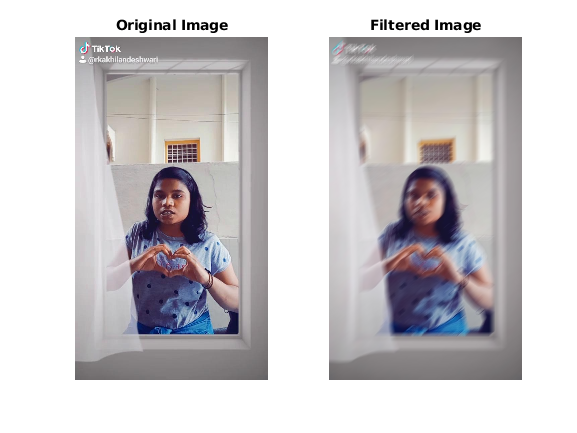

%Moving the pixels in the image
clf;
L=imread('/MATLAB Drive/V2F/120.jpg');
H = fspecial('motion', 23,40);
I2 = imfilter(L,H,'replicate');
subplot(1,2,1),imshow(L),title("Original Image");
subplot(1,2,2),imshow(I2),title("Filtered Image");

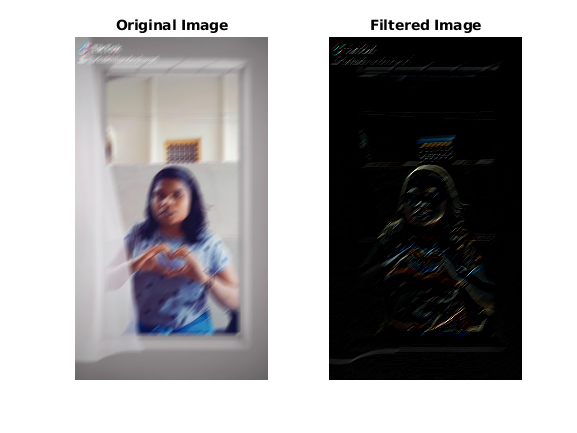

%Smoothing the above blured image
clf;
sm= fspecial('sobel');
s3 = imfilter( I2, sm );
subplot(1,2,1),imshow(I2),title("Original Image");
subplot(1,2,2),imshow(s3),title("Filtered Image");

## Demonstrate wavelets decomposition ( 2 to 3 levels)

load sumsin 
plot(sumsin)
title('Signal')

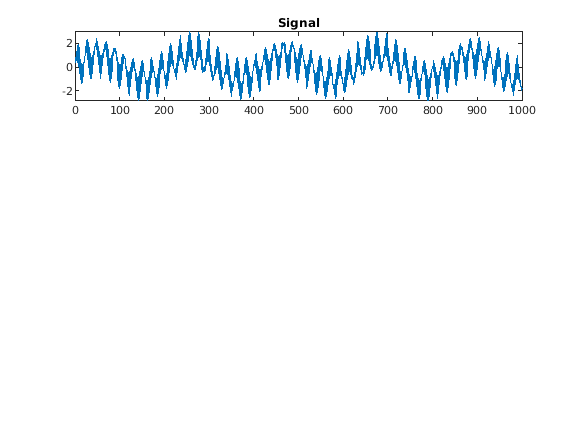

[c,l] = wavedec(sumsin,3,'db2');
approx = appcoef(c,l,'db2');

[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

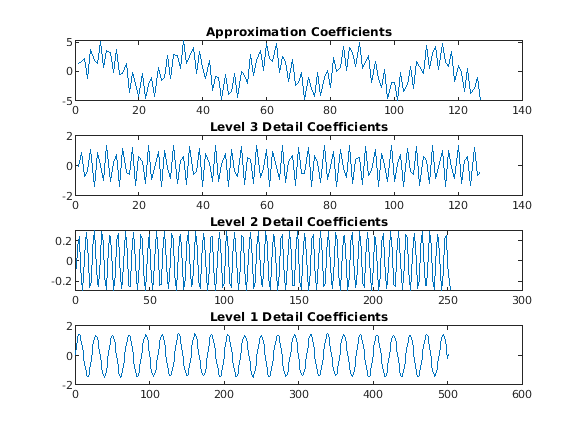

%Wave decomposition calling the user defined function
% First argument takes the image
% Second argument takes levels for decomposition
wave_decom('/MATLAB Drive/V2F/301.jpg',3)

## FUNCTION DEFINITION

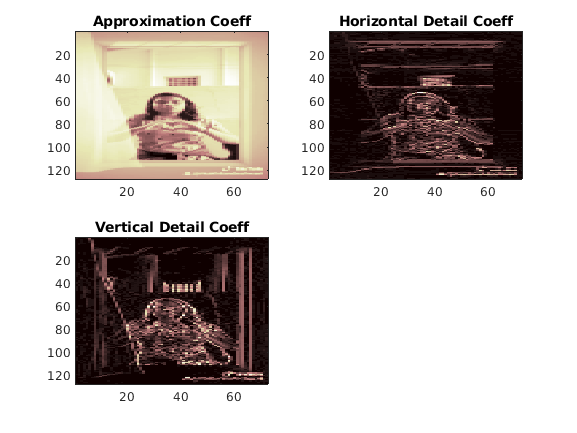

function x=wave_decom(img,l)

I=rgb2gray(imread(img));
[c,s]=wavedec2(I,l,'haar');
[H2,V2] = detcoef2('all',c,s,l);
A2 = appcoef2(c,s,'haar',l);
V2img = wcodemat(V2,255,'mat',1);
H2img = wcodemat(H2,255,'mat',1);
A2img = wcodemat(A2,255,'mat',1);
figure
colormap pink(230)
subplot(2,2,1);imagesc(A2img);title(['Approximation Coeff']);
subplot(2,2,2);imagesc(H2img);title('Horizontal Detail Coeff');
subplot(2,2,3);imagesc(V2img);title('Vertical Detail Coeff');
end